# Hankel Matrix Completion

## Experimenting with LTI's without input

First we get an intuition of state space definition without input. We deal with discrete systems, since we are interested in data sampled at specific time points in history.

% statenum states, outputnum outputs, 0 input
statenum = 100;
outputnum = 1;

state_space = drss(statenum,outputnum,0)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 0"
    "Number of outputs: 1"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:0"  
    "C_rows:1"      "C_cols:100"
    "D_rows:1"      "D_cols:0"  

Max absolute eigen value: 1
Eigen values of A: 
    0.9888
    0.9888
    0.9980
    0.9980
    0.8729
    0.8729
    0.8066
    0.8066
    0.9564
    0.9544
    0.9286
    0.9286
    0.9350
    0.9350
    0.8115
    0.9564
    0.9564
    0.6799
    0.6799
    0.7527
    0.9174
    0.9174
    0.9083
    0.9083
    0.7153
    0.6978
    0.6806
    0.5966
    0.5966
    0.6258
    0.6258
    0.6341
    0.7826
    0.7826
    0.7633
    0.7633
    0.4682
    0.4682
    0.9049
    0.5288
    0.5288
    0.5858
    0.5858
    0.8831
    0.4200
    0.4200
    0.4608
    0.8241
    0.8126
    0.4041
    0.4041
    1.0000
    1.0000
    1.0000
    0.7926
    0.3916
    0.3662
    0.3662
    0.7715
    0.7605
    0.3185
    0.3006
    0

Now we create a set of outputs, with x(0) = x_0 != 0 (since we dont have an input and thus if the state is the zero vector the transfer function will not do anything to the state)

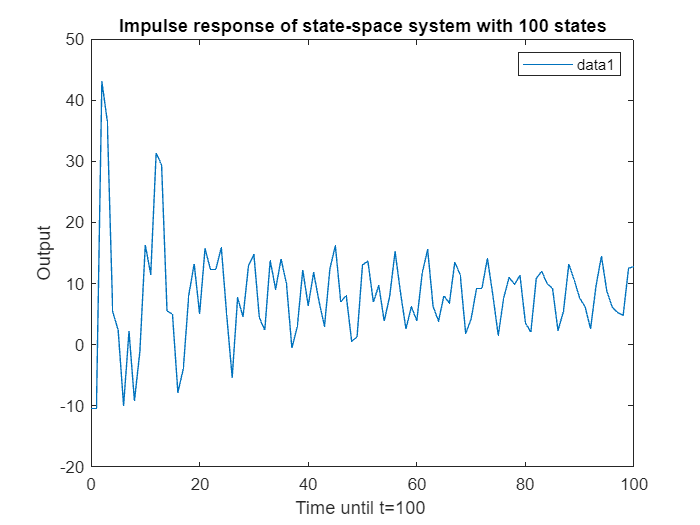

maxTime = 100;

figure;
dssplot(state_space,maxTime);

Notice that its possible for one of the eigenvalues to be exactly 1, which is neither stable nor unstable (marginally stable). Using the drss function we can generate many different kinds of discrete-time state-space systems that are stable. In the plot we observe that after a large enough T the impulse response stabilizes.

## Experimenting with LTI's with input

We can also generate an LTI with an input vector upon which a transformation B and D have an effect on the state change and output. We can have a single-input or multi-input.

% statenum states, outputnum outputs, inputnum input
statenum = 100;
outputnum = 4;
inputnum = 4;
maxTime = 100;
input = [2;1;2;3];


state_space = drss(statenum,outputnum,inputnum)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 4"
    "Number of outputs: 4"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:4"  
    "C_rows:4"      "C_cols:100"
    "D_rows:4"      "D_cols:4"  

Max absolute eigen value: 1
Eigen values of A: 
    0.8959
    0.8959
    0.9676
    0.9676
    0.8254
    0.8254
    0.9841
    0.9725
    0.9725
    0.6738
    0.6738
    0.9592
    0.9171
    1.0000
    1.0000
    0.8889
    0.7156
    0.7156
    0.8701
    0.8512
    0.8064
    0.6736
    0.6736
    0.8076
    0.5158
    0.5158
    0.7559
    0.5002
    0.5002
    0.5465
    0.5465
    0.7547
    0.7213
    0.7213
    0.7463
    0.7179
    0.7161
    0.7266
    0.4989
    0.4989
    0.6740
    0.7567
    0.6443
    0.5992
    0.5992
    0.5379
    0.5379
    0.7567
    0.5527
    0.5527
    0.6144
    0.5901
    0.5809
    0.3316
    0.3316
    0.5709
    0.5519
    0.5635
    0.4621
    0.4308
    0.5178
    0.2899
    0

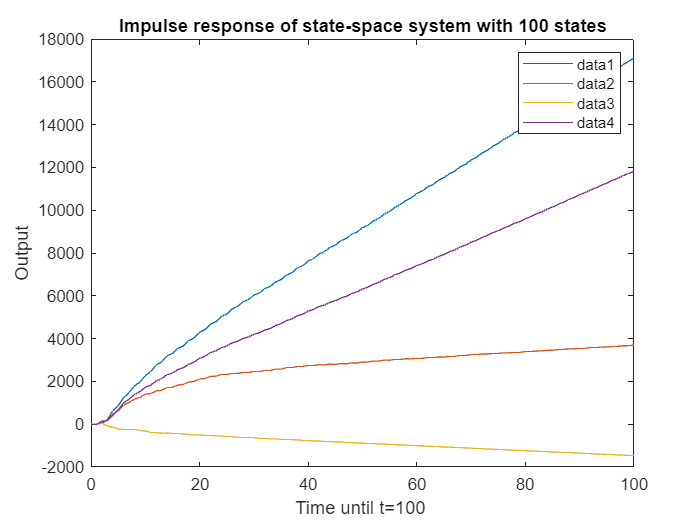

figure;
dssplot(state_space,maxTime,input);

Lets plot the trajectory of the impulse response with the old input and some new input.

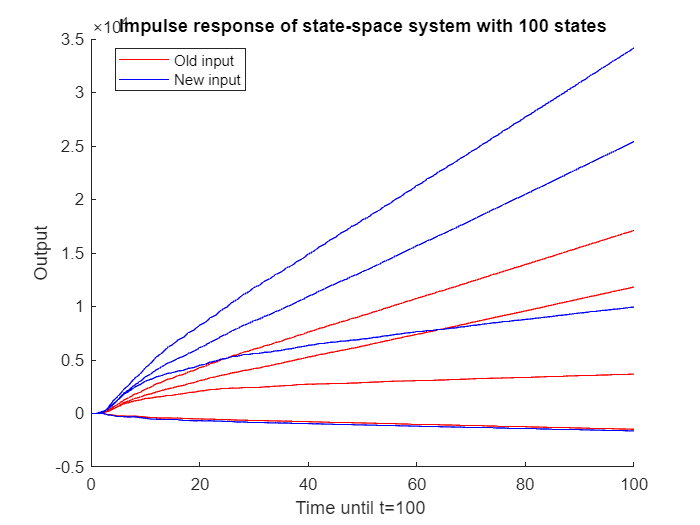

figure;
hold on
f1 = dssplot(state_space,maxTime,input);
f2 = dssplot(state_space,maxTime,[2;1;5;6]);
set(f1, 'Color', 'r');
set(f2, 'Color', 'b');
legend([f1(1), f2(1)], {'Old input', 'New input'}, 'Location', 'best');
hold off;

## Experimenting with Hankel Matrices

Now we're going to experiment with hankel matrices and show how it is relevant to time-series data.  Firstly, we create a drss and with a single in- and output and random initial conditions. We then convert the output to a hankel matrix.

input = 2;
inputnum = 1;
outputnum = 1; 
statenum = 3;
maxTime = 50;

dss = drss(statenum, outputnum, inputnum)

dss =
 
  A = 
            x1       x2       x3
   x1  0.06065  -0.2695  -0.3126
   x2  0.07955  -0.6069  -0.2257
   x3   0.0675    0.106  0.07304
 
  B = 
           u1
   x1       0
   x2  0.5629
   x3  0.1247
 
  C = 
             x1        x2        x3
   y1  -0.05896    -1.491         0
 
  D = 
            u1
   y1  -0.9044
 
Sample time: unspecified
Discrete-time state-space model.


[x,y] = dsssim(dss,maxTime,input)

x =     0.0156   -0.3921   -0.2635   -0.3082   -0.2812   -0.2958   -0.2881   -0.2922   -0.2901   -0.2912   -0.2906   -0.2909   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908   -0.2908
    0.9684    0.4440    0.7385    0.5894    0.6688    0.6264    0.6489    0.6370    0.6433    0.6399    0.6417    0.6408    0.6413    0.6410    0.6412    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0.6411    0

y =    -1.4446   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475


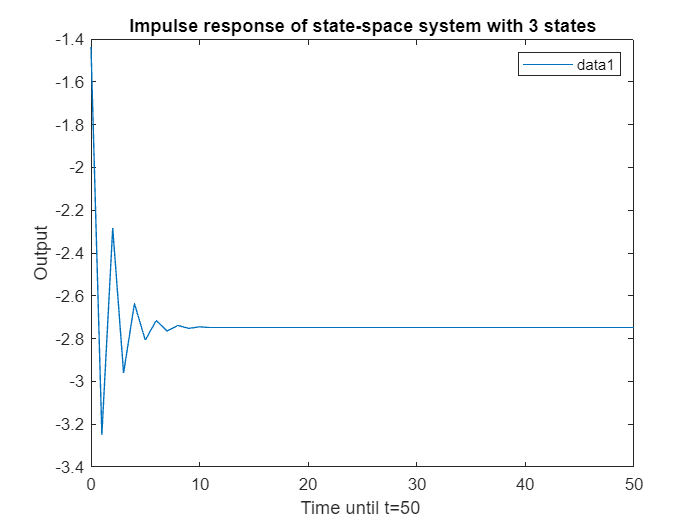

dssplot(dss,maxTime,input);

delta = 26

delta = 26

c = y(1,1:delta)

c =    -1.4446   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475


r =y(1,delta:size(y,2))

r =    -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475


H = hankel(c,r)

H =    -1.4446   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   

We can also use our hankelizeM function for quick hankel matrix generation with a specific lag length.

H = hankelizeM(y,26)

H =    -1.4446   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   

We can change the lag length to create different dimensions of our hankel matrix

hankelizeM(y,10)

ans =    -1.4446   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474  

hankelizeM(y,30)

ans =    -1.4446   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -3.2534   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -2.4476   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -2.8943   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473   -2.7475   -2.7474   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475   -2.7475
   -2.6694   -2.7892   -2.7253   -2.7593   -2.7412   -2.7508   -2.7457   -2.7484   -2.7470   -2.7477   -2.7473

We can view every row of the Hankel matrices as a sliding window over some data, which is why this offers insight into the inherent patterns and dynamics of the data/system. Once converted the data into this Hankel structure, it is possible to apply different decomposition techniques which we can then use e.g. in signal analysis to separate the main trend from noise. This structure and its sliding window over every row also offers contextual  features, which are important for forcasting and thus also relevant to our research.

## Experimenting with Hankel Matrix and making predictions

From here we can experiment with many different ways of predicting future outputs/points. 

### Hankel nuclear norm heuristic completion

We are now using the nuclear norm heuristic for completing the matrix as described in Dreesen, P., & Markovsky, I. (2019). Data-driven Simulation Using the Nuclear Norm Heuristic. *ICASSP, IEEE International Conference on Acoustics, Speech and Signal Processing - Proceedings*, *2019-May*. [https://doi.org/10.1109/ICASSP.2019.8682993.](https://doi.org/10.1109/ICASSP.2019.8682993.) We'll focus specifically on making future predictions

% Example time series data
data = sin(4 * (1:20))' + 0.05 * randn(20, 1);
dataLength = length(data);
L = 10;  % Number of lags (rows in the Hankel matrix)
N = dataLength - L + 1;  % Total columns in the Hankel matrix

% Create the full Hankel matrix without missing values initially
HankelMatrix = hankel(data(1:L), data(L:end));

% Define the number of points we want to predict (missing at the end)
numPredict = 2;

% Create a logical mask for the Hankel matrix with all ones (no missing data)
mask = true(size(HankelMatrix));

% Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
% These points appea5r in the last 'numPredict' rows of the last columns
for i = 1:numPredict
    mask(end-i+1, end-numPredict+i:end) = false;
end

% Now, apply the mask to set the last 'numPredict' points as NaN (missing)
HankelMatrix(~mask) = NaN;

% Display the mask and modified Hankel matrix to check
disp(mask);

   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   0
   1   1   1   1   1   1   1   1   1   0   0



disp(HankelMatrix);

    0.0454    0.2003    0.3231    0.4444    0.5566    0.5689    0.5696    0.6802    0.7302    0.9590    0.8604
    0.2003    0.3231    0.4444    0.5566    0.5689    0.5696    0.6802    0.7302    0.9590    0.8604    0.9694
    0.3231    0.4444    0.5566    0.5689    0.5696    0.6802    0.7302    0.9590    0.8604    0.9694    0.9539
    0.4444    0.5566    0.5689    0.5696    0.6802    0.7302    0.9590    0.8604    0.9694    0.9539    1.0299
    0.5566    0.5689    0.5696    0.6802    0.7302    0.9590    0.8604    0.9694    0.9539    1.0299    0.9593
    0.5689    0.5696    0.6802    0.7302    0.9590    0.8604    0.9694    0.9539    1.0299    0.9593    0.9295
    0.5696    0.6802    0.7302    0.9590    0.8604    0.9694    0.9539    1.0299    0.9593    0.9295    0.9205
    0.6802    0.7302    0.9590    0.8604    0.9694    0.9539    1.0299    0.9593    0.9295    0.9205    0.9983
    0.7302    0.9590    0.8604    0.9694    0.9539    1.0299    0.9593    0.9295    0.9205    0.9983       NaN
 

% Proceed with matrix completion using the nuclear norm minimization (using CVX)
cvx_begin sdp
    variable CompleteHankel(L, N)
    minimize(norm_nuc(CompleteHankel))
    subject to
        % Ensure the known entries remain the same
        CompleteHankel(mask) == HankelMatrix(mask);
cvx_end

 
Calling SDPT3 4.0: 232 variables, 107 equality constraints
------------------------------------------------------------

 num. of constraints = 107
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.9e-01|1.3e+01|5.3e+03| 2.721913e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.990|3.8e-08|2.3e-01|3.5e+02| 2.650311e+02  6.506453e+00| 0:0:00| chol  1  1 
 2|0.977|1.000|2.8e-08|1.0e-02|2.3e+01| 2.953038e+01  7.381619e+00| 0:0:00| chol  1  1 
 3|0.941|1.000|1.3e-08|1.0e-03|3.0e+00| 1.263841e+01  9.649727e+00| 0:0:00| chol  1  1 
 4|0.975|

% Check the completion status
disp(cvx_status);

Solved


% Extract the predicted values from the completed Hankel matrix
predictedValues = CompleteHankel(end, end-numPredict+1:end);
disp('Predicted values:');

Predicted values:


disp(predictedValues);

    0.7614    0.8190



disp(transpose(data(end-numPredict+1:end)))

    0.9374    0.8995



Results:

rmse(predictedValues,transpose(data(end-numPredict+1:end)))

ans = 0.1368

#### Notes on nuclear norm heuristic

- We can alternatively also try to compute the recurrence relation instead of solving the convex problem

- The most optimal value for L seems to be around when the lagged hankel matrix of the past trajectories H_L(w_d) is square

### Hankel alternative view of koopman

Check file ``i6220934_thesis_havok_experiments.mlx`` for more details